# Лабораторна робота No5

# Стиснення зображень

clear; close all; clc;

## **1. Завантаження чорнобілих та кольорових зображень**

I1 = imread('autumn.tif');
I2 = imread('cameraman.tif');

## 2. Перетворення кольорових в чорнобілі та вивід зображень

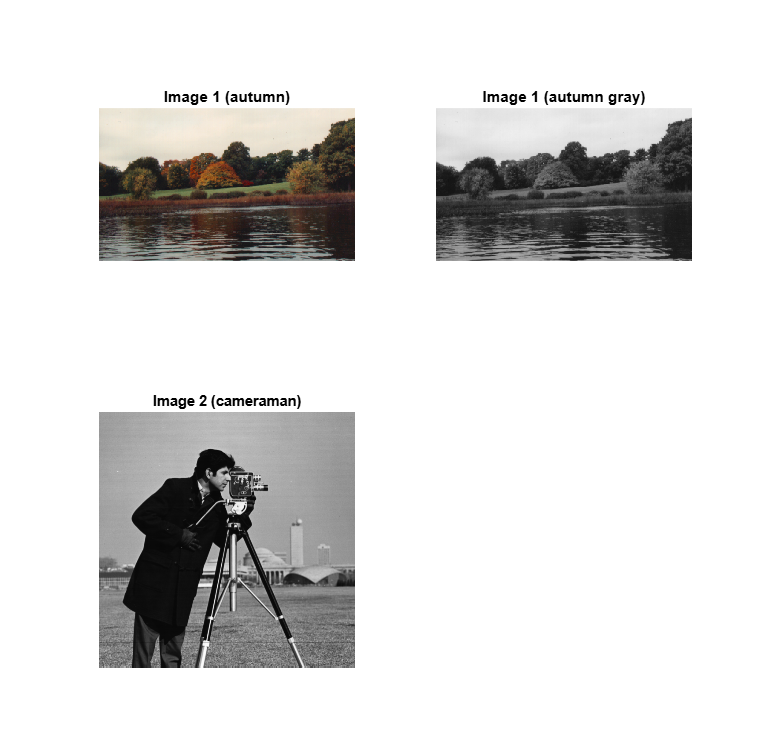

I1G = im2double(rgb2gray(I1));
I2G = im2double(I2);
figure;
subplot(2,2,1), imshow(I1), title('Image 1 (autumn)');
subplot(2,2,2), imshow(I1G), title('Image 1 (autumn gray)');
subplot(2,2,3), imshow(I2G), title('Image 2 (cameraman)');
truesize;

## 3. Виконати ДКП та відобразити з використанням лагорифмічного маштабу

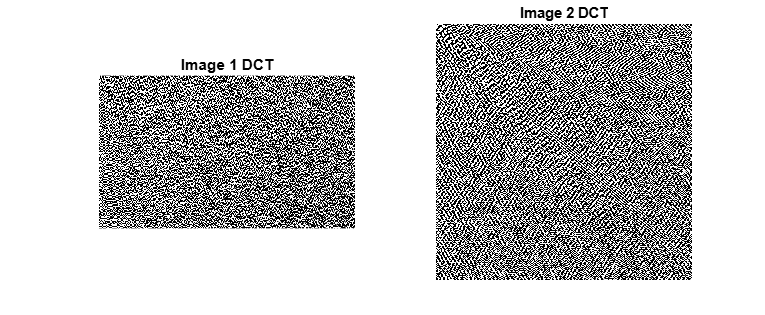

J1 = dct2(I1G);
J2 = dct2(I2G);
figure;
subplot(1,2,1), imshow(J1), title('Image 1 DCT');
subplot(1,2,2), imshow(J2), title('Image 2 DCT');
truesize;

## 4. Відновлення зображення за його ДКП спектром

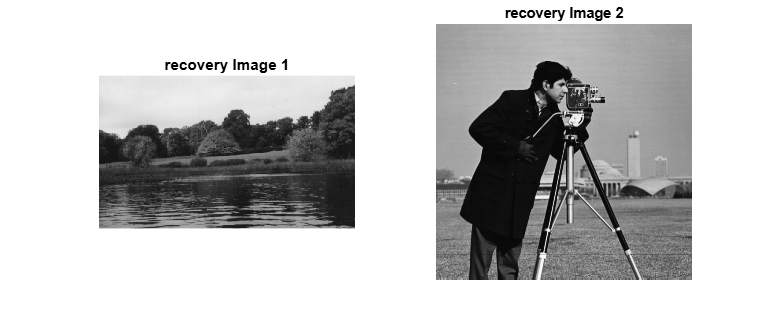

I1_recovery = idct2(J1);
I2_recovery = idct2(J2);

figure;
subplot(1,2,1), imshow(I1_recovery,[0 255]), title('recovery Image 1');
subplot(1,2,2), imshow(I2_recovery,[0 255]), title('recovery Image 2');
truesize;

## 5. Квантування

N = 5; % крок квантування
J1q_5 = N * round(J1 / N);
J2q_5 = N * round(J2 / N);

N = 30; % крок квантування
J1q_30 = N * round(J1 / N);
J2q_30 = N * round(J2 / N);

## 6.Відображення

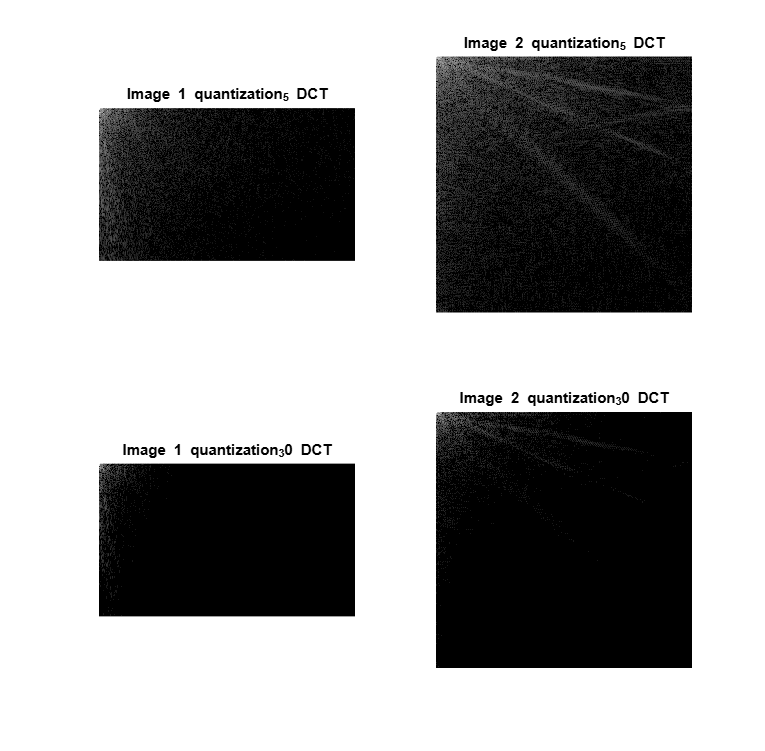

figure;
subplot(2,2,1), imshow(log(abs(J1q_5)),[]), title('Image 1 quantization_5 DCT');
subplot(2,2,2), imshow(log(abs(J2q_5)),[]), title('Image 2 quantization_5 DCT');
subplot(2,2,3), imshow(log(abs(J1q_30)),[]), title('Image 1 quantization_30 DCT');
subplot(2,2,4), imshow(log(abs(J2q_30)),[]), title('Image 2 quantization_30 DCT');
truesize;

## 7. Відновлення квантованого зображення

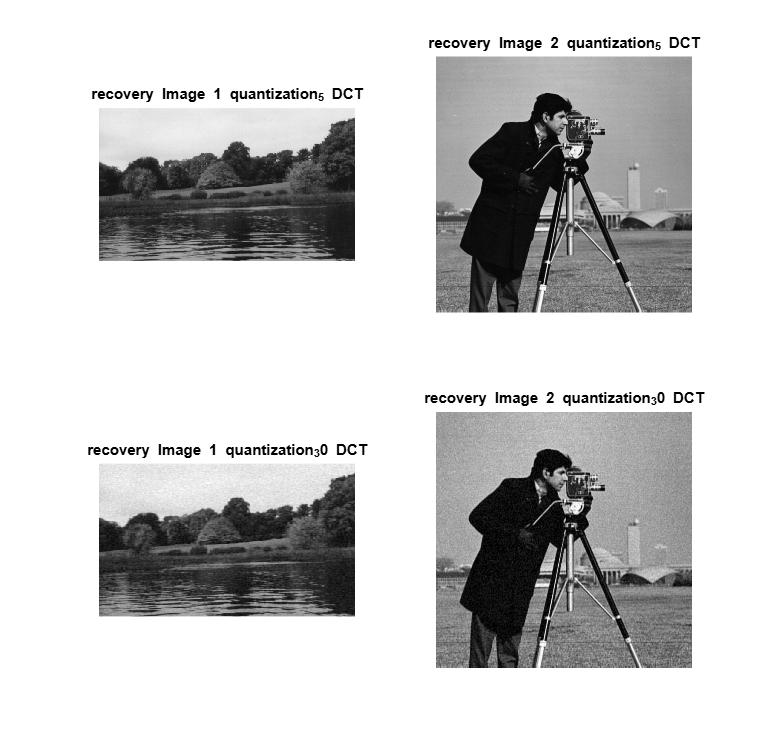

I1q_5_recovery = idct2(J1q_5);
I2q_5_recovery = idct2(J2q_5);
I1q_30_recovery = idct2(J1q_30);
I2q_30_recovery = idct2(J2q_30);
figure;
subplot(2,2,1), imshow(I1q_5_recovery,[0 255]), title('recovery Image 1 quantization_5 DCT');
subplot(2,2,2), imshow(I2q_5_recovery,[0 255]), title('recovery Image 2 quantization_5 DCT');
subplot(2,2,3), imshow(I1q_30_recovery,[0 255]), title('recovery Image 1 quantization_30 DCT');
subplot(2,2,4), imshow(I2q_30_recovery,[0 255]), title('recovery Image 2 quantization_30 DCT');
truesize;

## 8. Поясніть, яка мета досягається квантуванням коефіцієнтів ДКП.

Квантування коефіцієнтів ДКП зменшує розмір даних, відкидає менш важливі високочастотні компоненти та покращує ефективність кодування, забезпечуючи компроміс між якістю та стисненням зображення.

## 9. Квантування зображення без ДКП

Квантування вихідного зображення може зменшити розмір даних, але воно менш ефективне, ніж квантування коефіцієнтів ДКП, оскільки не враховує особливості людського сприйняття деталей.

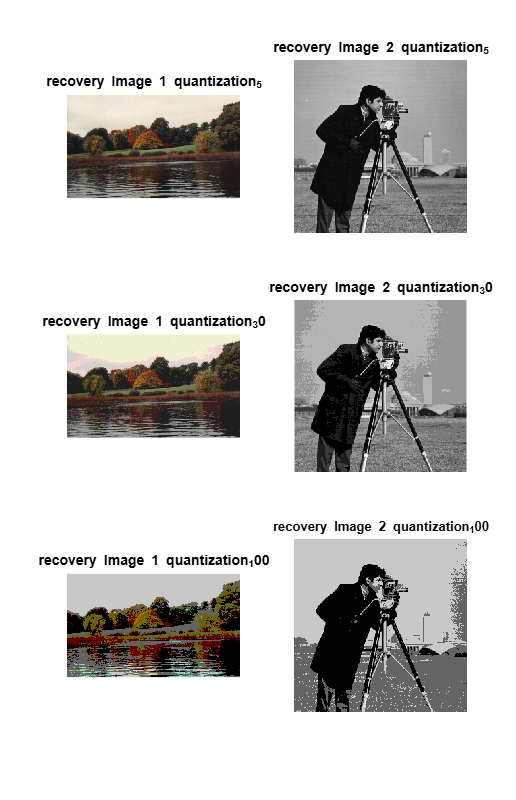

n = 5;
I1q_5 = round(double(I1)/n)*n;
I2q_5 = round(double(I2)/n)*n;

n = 30;
I1q_30 = round(double(I1)/n)*n;
I2q_30 = round(double(I2)/n)*n;

n = 100;
I1q_100 = round(double(I1)/n)*n;
I2q_100 = round(double(I2)/n)*n;

figure;
subplot(3,2,1), imshow(uint8(I1q_5)), title('recovery Image 1 quantization_5');
subplot(3,2,2), imshow(uint8(I2q_5)), title('recovery Image 2 quantization_5');
subplot(3,2,3), imshow(uint8(I1q_30)), title('recovery Image 1 quantization_30');
subplot(3,2,4), imshow(uint8(I2q_30)), title('recovery Image 2 quantization_30');
subplot(3,2,5), imshow(uint8(I1q_100)), title('recovery Image 1 quantization_100');
subplot(3,2,6), imshow(uint8(I2q_100)), title('recovery Image 2 quantization_100');
truesize;

## 10. Які недоліки ви бачите в стисненні зображень із використанням його ДКП і квантування коефіцієнтів ДКП?

Стиснення зображень через ДКП і квантування може спричинити втрати якості, блокові ефекти, постеризацію, зниження деталізації та труднощі з повторним редагуванням.